## **Soft Gripper Finger Actuation** 

A modular gripper finger is constructed by connecting rigid links using soft links that woud act like distributed joints. The soft links are allowed to bend about the z-axis with a strain order of 1 to enable the bending of the finger.

SorosimLinks (Soft and Rigid), and SorosimLinkage (Finger) are saved in GripperFinger`.mat`

load('GripperFinger.mat')

To see the properties of Soft

Soft

To see the properties of Rigid

Rigid

To see the properties of Finger

Finger

To see the problem definition:

Finger.plotq0

The result should be:

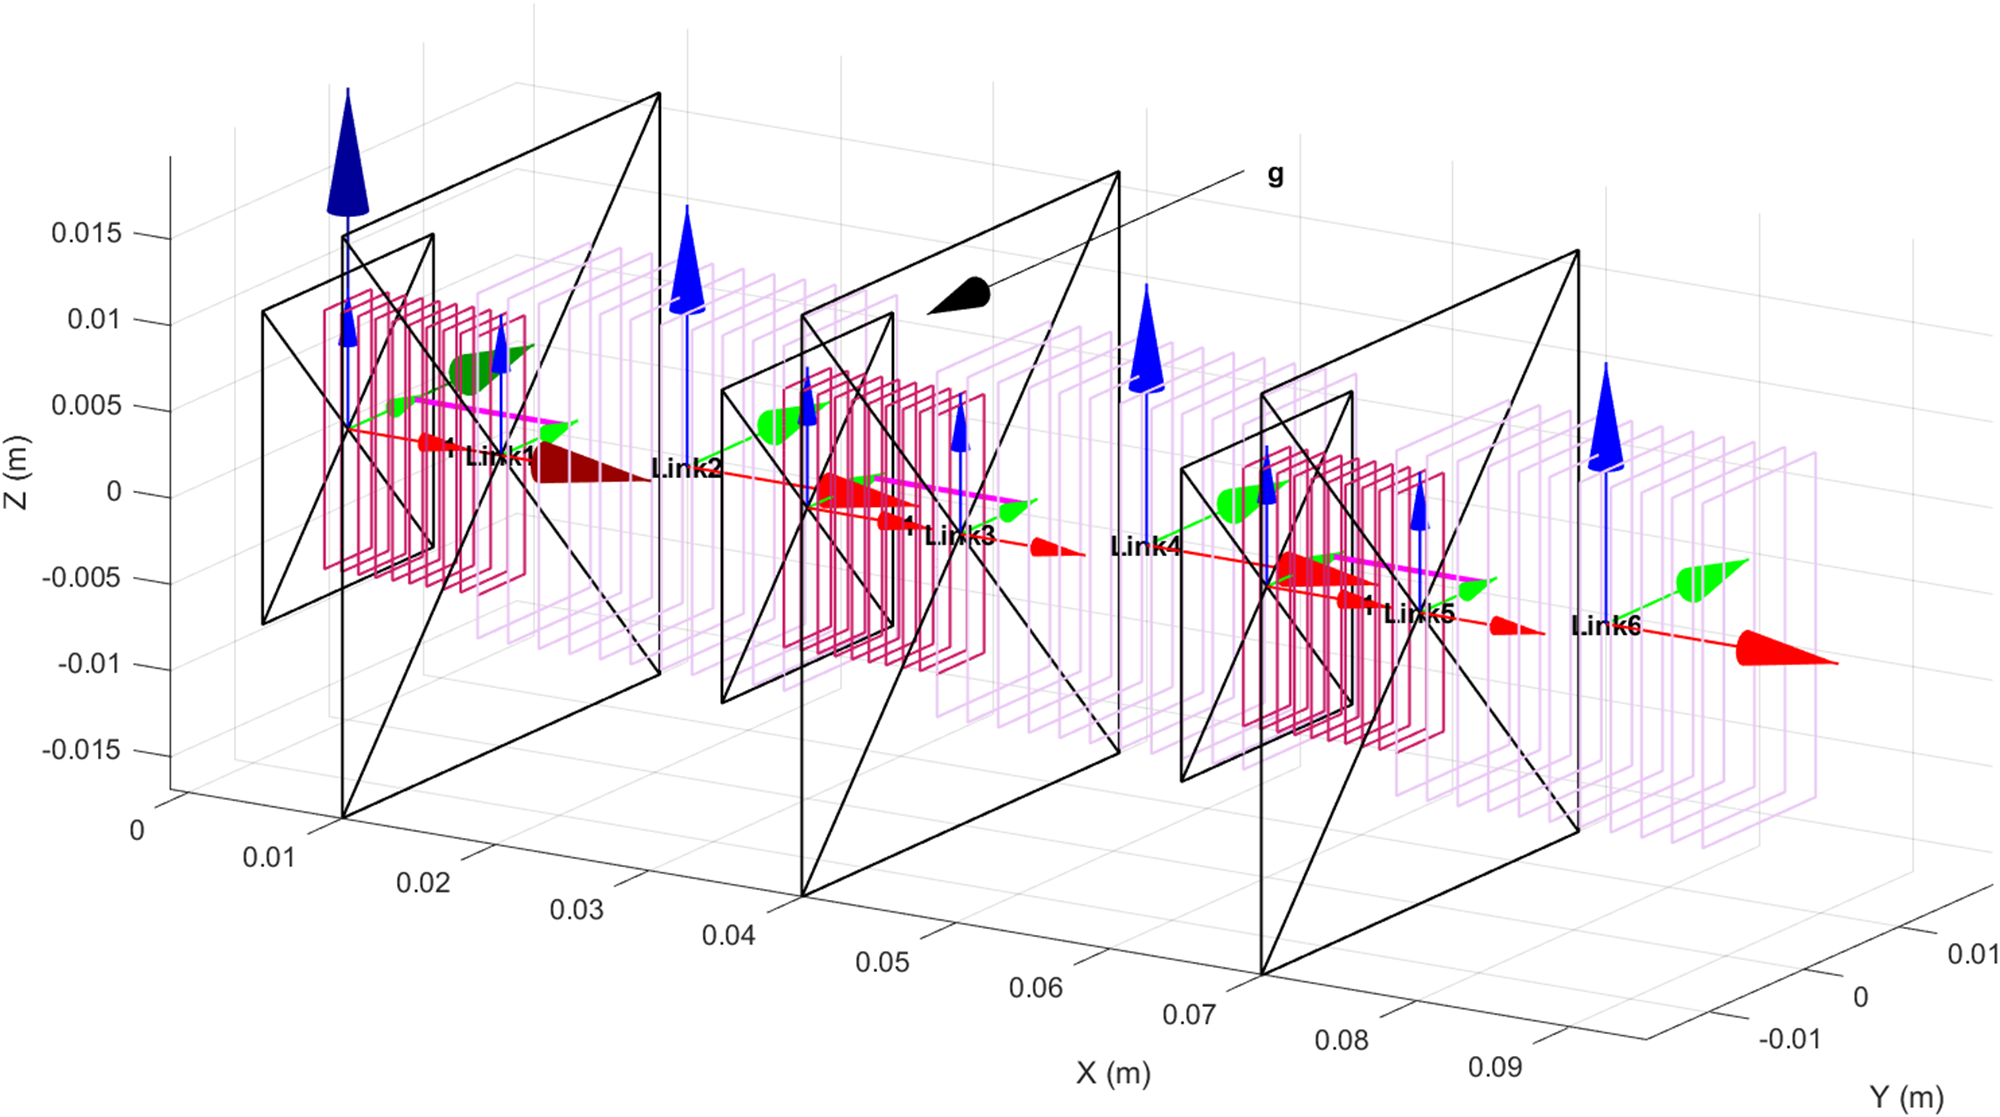

The gripper finger is rigidly fixed at one end and can be subjected to actuation forces.

### **Static equilibirum analysis**

For statics equilibirum analysis type:

q=Finger.statics;

Enter -2 N as the input actuation force into the cable in the command window when prompted. A dialog box will pop up, asking for the initial guess the user can choose the default value. 

The equilibirum solution is,

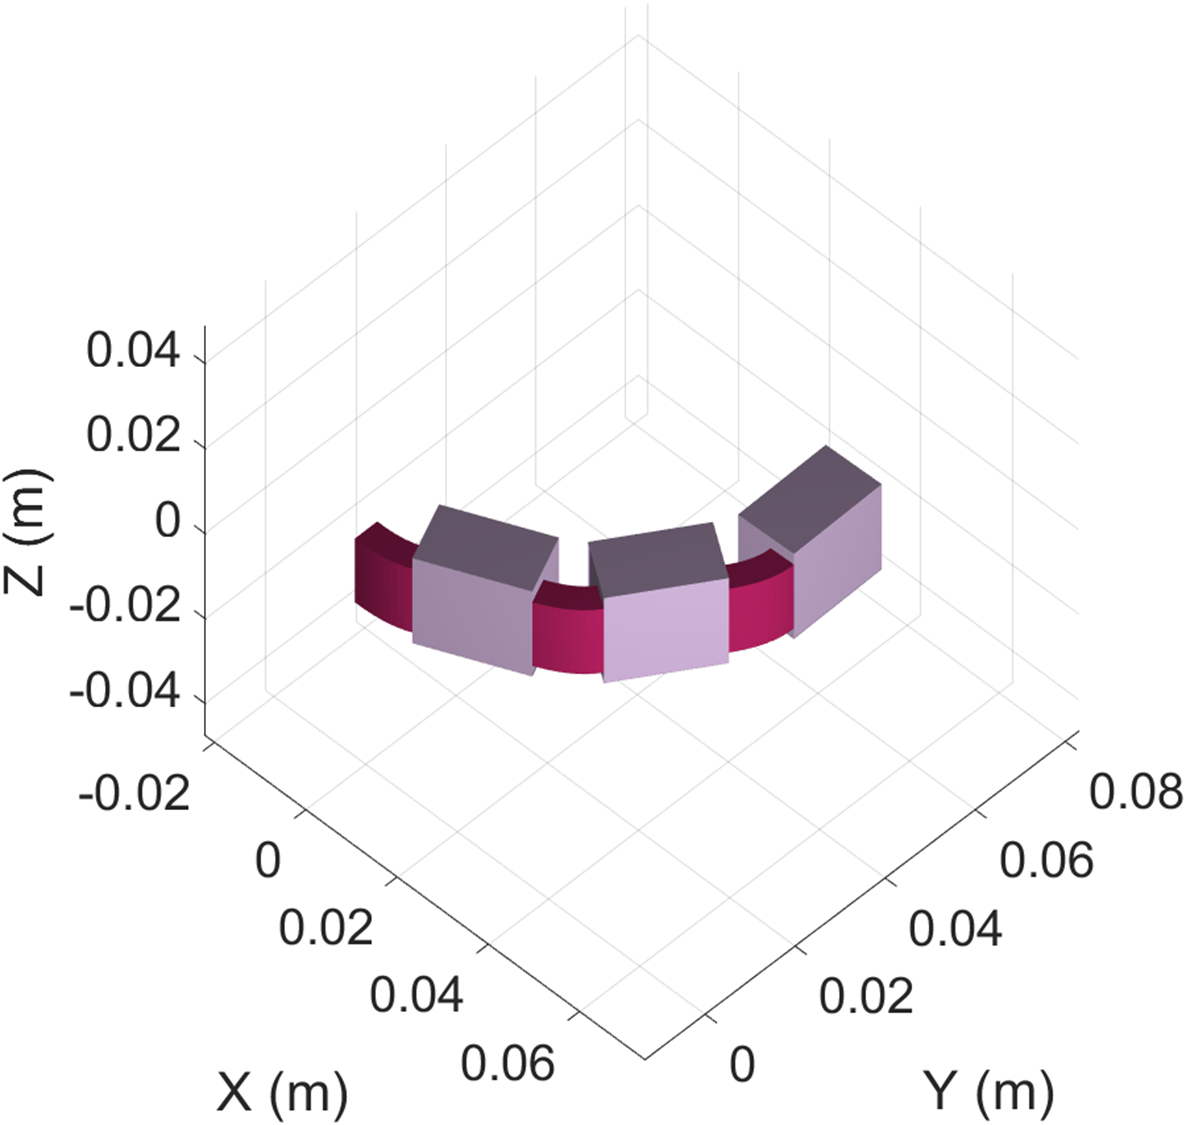

### **Dynamics (not recommended for this example)**

For dynamics problem, type:

[t,qqd]=Finger.dynamics;

The actuation input to the cable can be input by the user as a function of t in the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

Another dialog box will appear, asking the user if he/she wants to see a plot during the dynamic compulation. (this is slow and will not work in live script)

Dynamic compulation will take some time. Especially for this example the time is **very high.**

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will also take some time. 

A video named `Dynamics.avi` will be saved in the folder.